# Frequency Tuning

drcDir = 'D:\BarakH_codes\Sound_Pardigms\NP_Paradigm2\DRC Tuning';

maxDrcNum = size(dir([drcDir '/*.mat']),1);
DRC_TUNING_BASE_ID = 400;
DRC_TUNING_LAST_POSSIBLE_ID = 600;
nFirstChordsToIgnore = 0;  %5
iFreqToIgnore = 36; %Anomaly for highest frequency (too many responsive units) - removed in order to not bias the dataset for tuning analysis
% iFreqToIgnore = [];

Load all the relevant variables from data

% stimuli_times = 
% stimuli_stamps = 
% spike_times = 
% clusters_list =
% spike_clusters = 

### LOAD DRC Files

drcs = cell(maxDrcNum,1);
drcStartTimesSecAll = cell(maxDrcNum,1);
for iDrc = 1:maxDrcNum
    drcs{iDrc} = load([drcDir filesep sprintf('DRC_%03g.mat',iDrc)]);
    drcStartTimesSecAll{iDrc} = stimuli_times(stimuli_stamps==...
        (iDrc + DRC_TUNING_BASE_ID),1);
end


### Get DRC Tuning for each cluster

% clusters_list = spike_cluster_info.cluster_id;
% clusters_list = spike_cluster_channels.cluster_id;
nClus = numel(clusters_list);

for iClus = 1:nClus
    tic;
    spikeTimesSec = spike_times((spike_clusters) == clusters_list(iClus),:);
    response(iClus) = getDrcTuningAndContext(spikeTimesSec, ...
                    drcStartTimesSecAll, drcs,...
                    nFirstChordsToIgnore, [],iFreqToIgnore);
    if mod(iClus,50) == 0
        fprintf('Clus %d     %3gs\n',clusters_list(iClus),toc);
    end

end

Clus 77     0.703206s
Clus 188     0.726971s


### Plot significantBonferroni

Initialize an array to store the values

significantBonferroni = zeros(1, numel(response));

Loop through each element of response

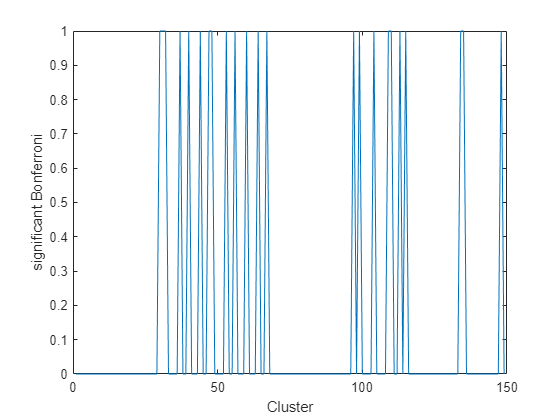

for i = 1:numel(response)
    significantBonferroni(i) = response(i).stats.significantBonferroni;
end
relevant_responses_indices = find(significantBonferroni);

figure()
plot(significantBonferroni)
xlabel('Cluster')
ylabel('significant Bonferroni')


relevant_responses = response(relevant_responses_indices);
relevant_responses_names = relevant_responses_indices;


### Plot Clusters

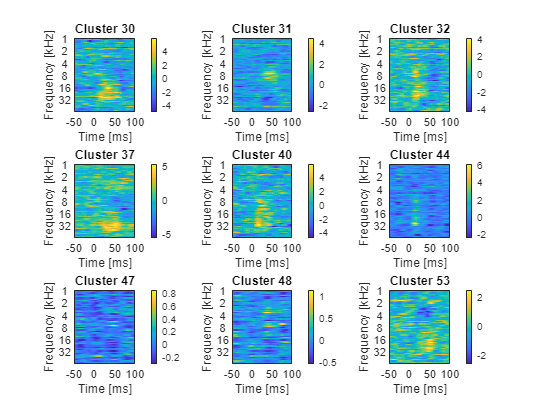

figure("Name",'Clusters')
set(gcf,'Color',[1 1 1])

num_subplots = 9;
n_rows = round(sqrt(num_subplots));
% relevant_responses_names = relevant_responses_names(26:50);

for ii = 1:num_subplots
    ind = ii;
    if ind>size(relevant_responses_names,2)
        break
    end
    
    subplot(n_rows, n_rows, ii);
    clus_pick = relevant_responses_names(ind);

    % Define Gaussian smoothing window
    gaussSmoothWin = getGaussWin(7, 20)';

    % Plot the response
    imagesc(response(clus_pick).timesPsthMs, 1:length(response(clus_pick).freqs.valid), ...
        conv2(response(clus_pick).psthPerFreq, gaussSmoothWin, 'same'));

    % Set Y-axis ticks and labels
    relevantIndices = find(abs(log(response(clus_pick).freqs.valid./round(response(clus_pick).freqs.valid))) < 1e-11);
    set(gca, 'YTick', relevantIndices, 'YTickLabel', response(clus_pick).freqs.valid(relevantIndices) / 1000);

    title(sprintf("Cluster %d", clus_pick));
    colorbar;
    xlabel('Time [ms]');
    ylabel('Frequency [kHz]');
end

## Some other Plots that can be used

% imagesc(response(clus_pick).psthPerNChordsFromPreviousToneNormalizedHz)
% imagesc(response(clus_pick).linearSumPerNChordsFromPreviousTone)

% figure()
% plot(response(clus_pick).AllDrcs.timesMs, response(clus_pick).AllDrcs.psthFr)